%例3.1
R=rotx(30*pi/180)

R =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


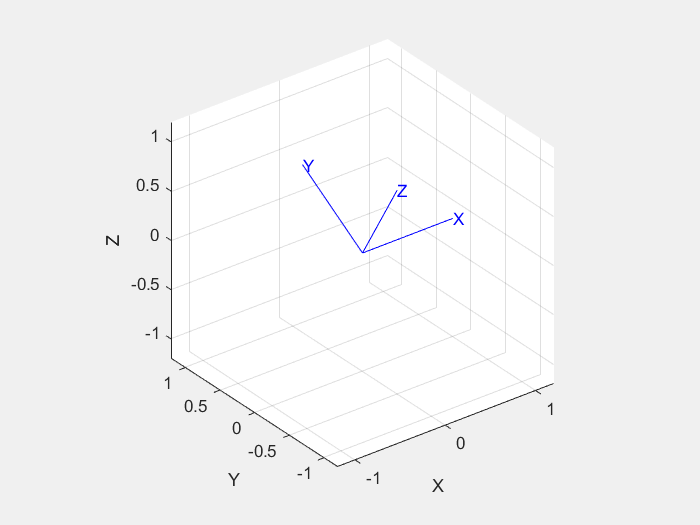

trplot(R)

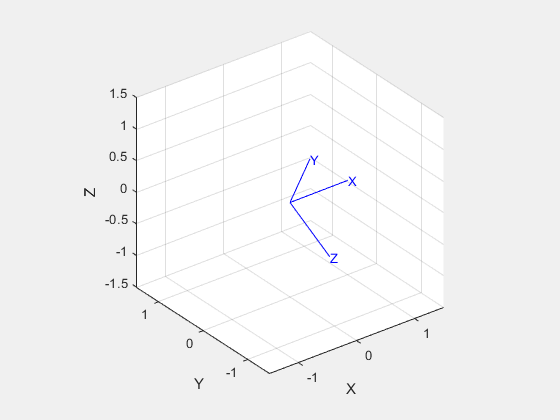

%例3.2
R=rotx(0);
R2=rotx(90);
tranimate(R,R2)
saveas(gcf,'3.2.jpg')

%例3.3
T=transl(1,2,3)

T =      1     0     0     1
     0     1     0     2
     0     0     1     3
     0     0     0     1


p=[2 3 4];
T=transl(p)

T =      1     0     0     2
     0     1     0     3
     0     0     1     4
     0     0     0     1


%例3.4
T=transl(3,4,5);
p=transl(T)

p =      3
     4
     5


[x,y,z]=transl(T)

x = 3

y = 4

z = 5

%例3.5
T=trotx(pi/6)*transl(3,4,5)

T =     1.0000         0         0    3.0000
         0    0.8660   -0.5000    0.9641
         0    0.5000    0.8660    6.3301
         0         0         0    1.0000


R=t2r(T)

R =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


%例3.6
R=rotz(pi/3)

R =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


T=r2t(R)

T =     0.5000   -0.8660         0         0
    0.8660    0.5000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


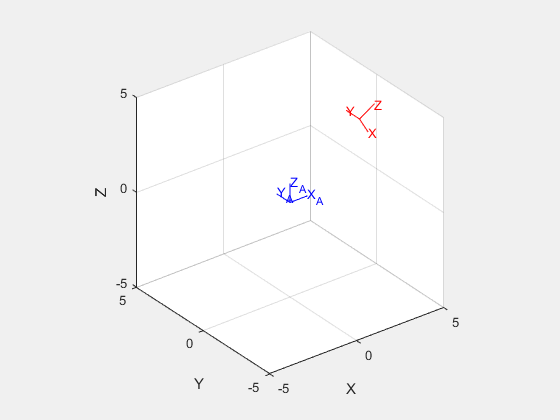

%例3.7 存在问题，待改
T1=troty(pi/3);
T2=transl(4,0,3);
T=T2*T1;
p1=[2;4;3;1];
Tr=inv(T);
ap1=Tr*p1;
T0=transl(0,0,0);
trplot(T0,'frame','A','color','b');
axis([-5 5 -5 5 -5 5]);
hold on
tranimate(T0,T,'frame,','B','color','r')
saveas(gcf,'3.7.jpg')

% 教材P34例2.6
T0=[0.527 -0.574 0.628;0.396 0.819 0.439;-0.766 0 0.643];
F=transl(5,3,8)*r2t(T0)

F =     0.5270   -0.5740    0.6280    5.0000
    0.3960    0.8190    0.4390    3.0000
   -0.7660         0    0.6430    8.0000
         0         0         0    1.0000


T1=transl(0,10,5);
Fn=T1*F

Fn =     0.5270   -0.5740    0.6280    5.0000
    0.3960    0.8190    0.4390   13.0000
   -0.7660         0    0.6430   13.0000
         0         0         0    1.0000


trplot(F,'frame','o','color','b');

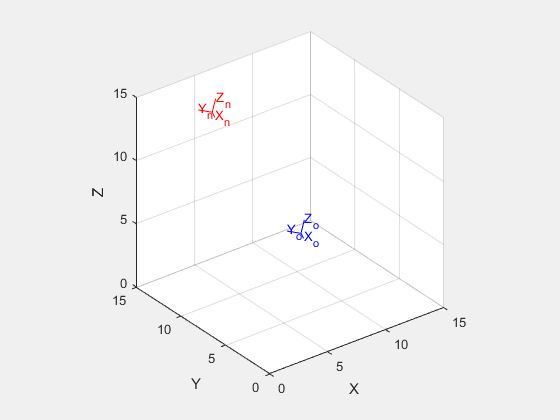

axis([0 15 0 15 0 15]);
hold on
tranimate(F,Fn,'frame','n','color','r')
hold off
saveas(gcf,'2.6.jpg')

% 教材P36例2.7
p1=[2;3;4;1]

p1 =      2
     3
     4
     1


T0=transl(0,0,0);
T=trotx(pi/2);
p2=T*p1

p2 =      2
    -4
     3
     1


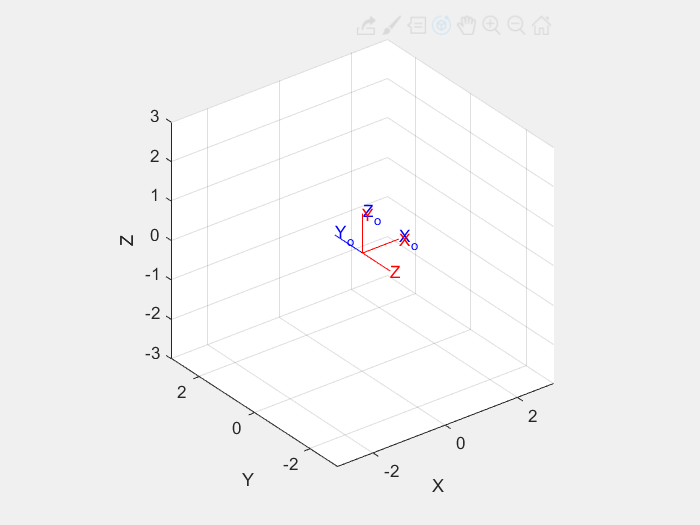

trplot(T0,'frame','o','color','b');
axis([-3 3 -3 3 -3 3]);
hold on
tranimate(T0,T,'frame,','n','color','r')

% 教材P38例2.9
p1=[7;3;1;1];
T0=transl(0,0,0);
T1=trotz(pi/2);
T2=transl(4,-3,7);
T3=troty(pi/2);
T=T3*T2*T1;
p2=T*p1

p2 =      8
     4
    -1
     1


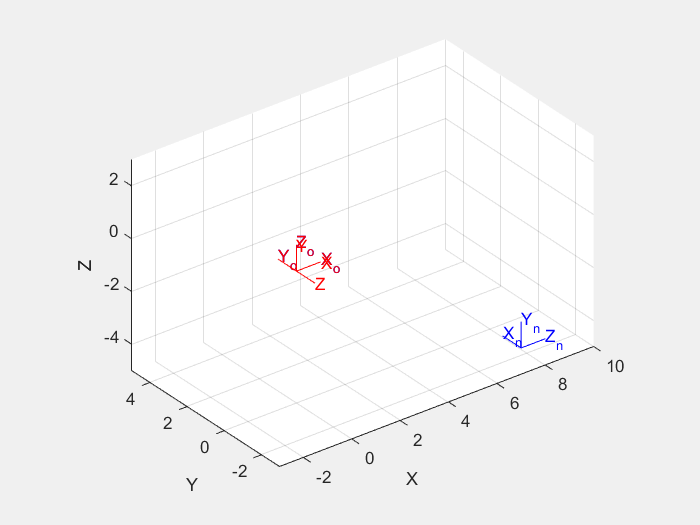

trplot(T0,'frame','o','color','r');
axis([-3 10 -3 5 -5 3])
hold on
tranimate(T0,T,'frame','n','color','b')

% 教材P40例2.11
T0=transl(0,0,0);
T1=trotx(pi/2);
T2=transl(0,0,3);
T3=trotz(pi/2);
T4=transl(0,5,0);
T=T3*T1*T2*T4;
p1=[1;5;4;1]

p1 =      1
     5
     4
     1


p2=T*p1

p2 =      7
     1
    10
     1


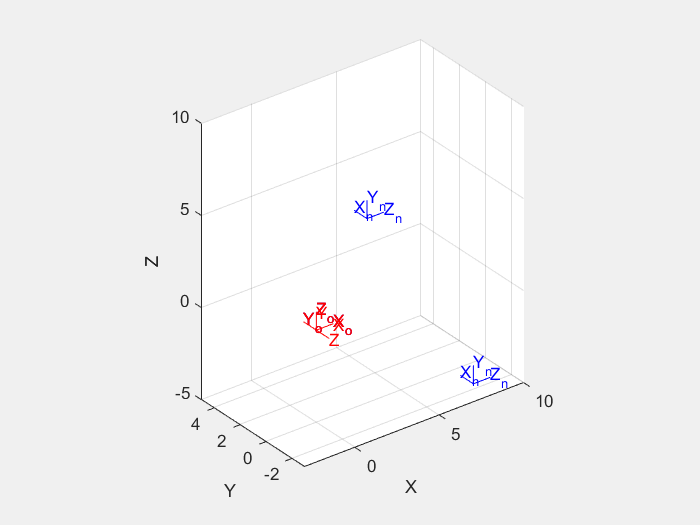

trplot(T0,'frame','o','color','r');
axis([-3 10 -3 5 -5 10])
hold on
tranimate(T0,T,'frame','n','color','b')